# Slosh 3D - Rotation about z

YX parametrization of the pendulum

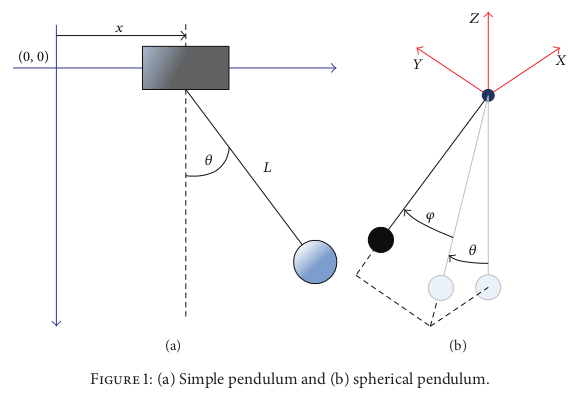

In this code the equation of motion for the pendulum angle representing the sloshing are derived through the use of the Euler-Lagrange equations.

This sloshing model represent only the 3D motion of the tray and a 1D rotation about the z axis of the container.

clc 
clear all

syms gamma(t) phi_c(t) theta(t) psi(t) phi(t)
syms t 
syms dx(t) dy(t) dz(t) h l_n m_n g M b J cs L_n
syms x(t) y(t) z(t) xc(t) yc(t) zc(t)
sympref('AbbreviateOutput',false);

assume(h > 0)
assume(m_n > 0)
assume(g > 0)
assume(l_n > 0)

matlab_function_generation = false;
rot = "z";

$\theta$ = angle between plane ZY and the mass, angle of the pendulum mapped in xz plane

$\phi$ = angle in the perpendicular direction, between the original pendulum and the mapped pendulum

$\phi_c$ = rotation of the container about its longitudinal axis

$\gamma$ = rotation of the pendulum about its longitudinal axis

l = length of pendulum

m = mass of pendulum

M = mass of liquid + container

b = damping coefficient

J = moment of inertia of the pendulum mass

## Derivation of the pendulum coordinates

Through the use of homogeneous transformation matrices infer the position of the pendulum mass and of the liquid+container mass in the world reference frame.

Assume the following reference frames:

- Inertial frame

- Frame of the container with origin coincident with the pivot of the pendulum

- Frame of the liquid object with origin coincident with the pivot of the pendulum

- Frame of the pivot of the pendulum

- Frame of the pendulum mass

### World to liquid

Derive the homogeneous transformation matrix from the world to the liquid reference frame.

The transformation from inertial frame to container frame will be skipped because the dependance of the rotation of the container is mapped into the rotation of the liquid through a friction interaction.

Define rotation matrix (rotation of around the z-axis)

R_z_gamma = [cos(gamma), -sin(gamma), 0;
               sin(gamma), cos(gamma), 0;
               0,         0,        1];
R_z_gamma = formula(R_z_gamma);

Define translation vector

p = [x; y; z+h-L_n];
% p = [x; y; z];

Create homogeneous transformation matrix

T_wl = [R_z_gamma, p; 0 0 0 1];
T_wl = formula(T_wl);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from world to liquid:');

Homogeneous Transformation Matrix from world to liquid:


disp(T_wl);

$$\left(\begin{array}{cccc} \cos\left(\gamma \left(t\right)\right) & -\sin\left(\gamma \left(t\right)\right) & 0 & x\left(t\right)\\ \sin\left(\gamma \left(t\right)\right) & \cos\left(\gamma \left(t\right)\right) & 0 & y\left(t\right)\\ 0 & 0 & 1 & h-L_{n}+z\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Liquid to pivot

Derive the homogeneous transformation matrix from the liquid refernce frame to the pivot reference frame.

Define rotation matrices

% Rotation matrix about y-axis of angle -theta
R_y_theta = [cos(theta),  0, sin(theta); 
             0,           1,           0; 
             -sin(theta),  0,  cos(theta)];
R_y_theta = formula(R_y_theta);

% Rotation matrix about x-axis of angle phi
R_x_phi = [1,          0,          0; 
           0,   cos(phi),  -sin(phi); 
           0,   sin(phi),  cos(phi)];
R_x_phi=formula(R_x_phi);

R_combined = R_y_theta * R_x_phi;

Define translation vector

p = [0; 0; 0];

Create homogeneous transformation matrix

T_lp = [R_combined, p; 0 0 0 1];
T_lp = formula(T_lp);

% Display the transformation matrix
% disp('Homogeneous Transformation Matrix from liquid to pivot:');
% disp(T_lp);

### Pivot to Pendulum mass

R = eye(3);

Define translation vector

p = [0; 0; -l_n];

Define the position of the pendulum mass in the static reference frame fixed to the pivot

T_pm = [R, p; 0 0 0 1];
T_pm = formula(T_pm);

% Display the transformation matrix
% disp('Homogeneous Transformation Matrix from pivot to mass:');
% disp(T_pm);


$$p_m =$$

$$\left(\begin{array}{c}
l\,\cos \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\\
l\,\sin \left(\phi \left(t\right)\right)\\
-l\,\cos \left(\phi \left(t\right)\right)\,\cos \left(\theta \left(t\right)\right)
\end{array}\right)$$


### Pendulum mass coordinates in inertial frame

Derive the homogeneous transformation from inertial frame to pendulum mass.

T_wm = T_wl*T_lp*T_pm

$$T\_wm = \left(\begin{array}{cccc} \cos\left(\gamma \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) & \cos\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-\cos\left(\varphi \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right) & \sin\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)+\cos\left(\gamma \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & x\left(t\right)-l_{n}\,\left(\sin\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)+\cos\left(\gamma \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)\\ \cos\left(\theta \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right) & \cos\left(\gamma \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)+\sin\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-\cos\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & y\left(t\right)+l_{n}\,\left(\cos\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)-\cos\left(\varphi \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)\\ -\sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) & h-L_{n}+z\left(t\right)-l_{n}\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Derive the coordinates of the pendulum mass

xm = T_wm(1,4)

$$xm = x\left(t\right)-l_{n}\,\left(\sin\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)+\cos\left(\gamma \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)$$

ym = T_wm(2,4)

$$ym = y\left(t\right)+l_{n}\,\left(\cos\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)-\cos\left(\varphi \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)$$

zm = T_wm(3,4)

$$zm = h-L_{n}+z\left(t\right)-l_{n}\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)$$


% xr = xm - x
% yr = ym - y
% zr = zm - z

% % if theta = neg
% xr = l_n*cos(phi)*sin(theta);
% yr = l_n*sin(phi);
% zr = -l_n*cos(phi)*cos(theta);

% if theta = pos
xr = -l_n*cos(phi)*sin(theta);
yr = l_n*sin(phi);
zr = -l_n*cos(phi)*cos(theta);

## Derivation of the container coordinates

To be pedantic, the transformation between the world and the container reference frame is as follows

### World to container

Derive the homogeneous transformation matrix from the world to the container reference frame.

Define rotation matrix (rotation of around the z-axis)

R_z_phi_c = [cos(phi_c), -sin(phi_c), 0;
             sin(phi_c),  cos(phi_c), 0;
             0,           0,          1];
R_z_phi_c = formula(R_z_phi_c);

Define translation vector

p = [x; y; z];

Create homogeneous transformation matrix

T_wc = [R_z_phi_c, p; 0 0 0 1];
T_wc = formula(T_wc);

% Display the transformation matrix
% disp('Homogeneous Transformation Matrix from world to container:');
% disp(T_wc);

## Derivation of the equations of motion

Derive the equation of motion finding kinetic and potential energies and then assembling the lagrangian equation with respect to theta.

### Kinetic Energy

xm_dot = diff(xm, t);
ym_dot = diff(ym, t);
zm_dot = diff(zm, t);

xr_dot = diff(xr, t);
yr_dot = diff(yr, t);
zr_dot = diff(zr, t);

wp = diff(gamma, t);
wp_dot = diff(gamma, t, t);

wc = diff(phi_c, t);

#### Kinetic energy for the pendulum

Sum the contributions of the kinetic energies in x, y and z

Tmx = 0.5 * m_n * xm_dot^2;
% Tmx = simplify(Tmx);
%disp(latex(Tmx))

Tmy = 0.5 * m_n * ym_dot^2;
% Tmy = simplify(Tmy)
%disp(latex(Tmx))

Tmz = 0.5 * m_n * zm_dot^2;
% Tmz = simplify(Tmz)
%disp(latex(Tmz))

Tm = Tmx + Tmy + Tmz;
T = Tm;
simplify(T)

### Potential energy

%% Potential energy
Um = m_n * g * zm;

U = Um;
U = simplify(U);
disp("Potential energy:");

Potential energy:


disp(U);

$$-g\,m_{n}\,\left(L_{n}-h-z\left(t\right)+l_{n}\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)$$

### Rayleigh function

To account for dissipied energy

theta_dot = diff(theta, t);
phi_dot = diff(phi, t);

v2_theta = xr_dot^2 + yr_dot^2+ zr_dot^2;

D_t = b/2 *(v2_theta);
D_p = b/2 *(v2_theta);


D_dthetadot = diff(D_t, theta_dot);
D_dphidot = diff(D_p, phi_dot);

### Lagrangian

%% Lagrangian 
L = T - U;
L = simplify(L);

% wrt theta
L_thetadot = diff(L, diff(theta(t), t));
L_thetadot = simplify(L_thetadot);

dL_theta_dot = diff(L_thetadot, t);
dL_theta_dot = simplify(dL_theta_dot);

L_theta = diff(L, theta(t));
L_theta = simplify(L_theta);

% wrt phi
L_phi_dot = diff(L, diff(phi(t), t));
L_phi_dot = simplify(L_phi_dot);

dL_phi_dot = diff(L_phi_dot, t);
dL_phi_dot = simplify(dL_phi_dot);

L_phi = diff(L, phi(t));
L_phi = simplify(L_phi);

### Equations of motion

#### Theta

%for theta, that represents the swing of the pendulum and, accordingly, the sloshing dynamics.
eqn_theta = dL_theta_dot - L_theta + D_dthetadot;
% eqn_theta = eqn_theta + b * diff(theta, t);
eqn_theta = simplify(eqn_theta);
disp("Equation of motion with respect to theta:");

Equation of motion with respect to theta:


disp(eqn_theta);

$$l_{n}\,\cos\left(\varphi \left(t\right)\right)\,\left(m_{n}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}z\left(t\right)+g\,m_{n}\,\sin\left(\theta \left(t\right)\right)+b\,l_{n}\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-m_{n}\,\cos\left(\gamma \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-m_{n}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+l_{n}\,m_{n}\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+l_{n}\,m_{n}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\gamma \left(t\right)-2\,l_{n}\,m_{n}\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)-l_{n}\,m_{n}\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\gamma \left(t\right)\right)}^{2}+2\,l_{n}\,m_{n}\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\,\frac{\partial }{\partial t}\gamma \left(t\right)\right)$$

disp("Latex Equation of motion with respect to theta:");

Latex Equation of motion with respect to theta:


disp(latex(eqn_theta));

l_{n}\,\cos\left(\phi \left(t\right)\right)\,\left(m_{n}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} z\left(t\right)+g\,m_{n}\,\sin\left(\theta \left(t\right)\right)+b\,l_{n}\,\cos\left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t} \theta \left(t\right)-m_{n}\,\cos\left(\Gamma \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} x\left(t\right)-m_{n}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\Gamma \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} y\left(t\right)+l_{n}\,m_{n}\,\cos\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} \theta \left(t\right)+l_{n}\,m_{n}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} \Gamma \left(t\right)-2\,l_{n}\,m_{n}\,\sin\left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t} \theta \left(t\right)\,\frac{\partial }{\partial t} \phi \left(t\right)-l_{n}\,m_{n}\,\cos\left

eqn1 = isolate(eqn_theta == 0, diff(theta(t),t,t));
disp(eqn1);

$$\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{m_{n}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}z\left(t\right)+g\,m_{n}\,\sin\left(\theta \left(t\right)\right)+b\,l_{n}\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-m_{n}\,\cos\left(\gamma \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-m_{n}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+l_{n}\,m_{n}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\gamma \left(t\right)-2\,l_{n}\,m_{n}\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)-l_{n}\,m_{n}\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\gamma \left(t\right)\right)}^{2}+2\,l_{n}\,m_{n}\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\,\frac{\partial }{\partial t}\gamma \left(t\right)}{l_{n}\,m_{n}\,\cos\left(\varphi \left(t\right)\right)}$$

Simplify notation 

% syms c_theta s_theta c_phi s_phi c_gamma s_gamma
% syms theta_dot theta_ddot phi_dot phi_ddot x_ddot y_ddot z_ddot gamma_dot gamma_ddot
% eq_sub1 = subs(eqn_theta,[cos(theta(t)), sin(theta(t)), cos(phi(t)),sin(phi(t)), cos(gamma(t)),sin(gamma(t))],[c_theta s_theta c_phi s_phi c_gamma s_gamma]);
% eq_sub2 = subs(eq_sub1, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(x(t),t),t),diff(diff(y(t),t),t),diff(diff(z(t),t),t), diff(diff(gamma(t),t),t)],[theta_ddot,phi_ddot,x_ddot,y_ddot,z_ddot, gamma_ddot]);
% eq_sub3 = subs(eq_sub2, [diff(theta(t),t),diff(phi(t),t),diff(gamma(t),t)],[theta_dot,phi_dot,gamma_dot]);
% eq_sub3 = simplify(eq_sub3);
% 
% % eqn1 = isolate(eqn_theta == 0, diff(theta(t),t,t));
% eqn1 = isolate(eq_sub3 == 0, theta_ddot);
% eqn1 = collect(eqn1, [x_ddot, y_ddot, z_ddot, g, gamma_dot^2, gamma_ddot, phi_dot^2, phi_ddot, theta_dot]);
% disp(eqn1);
% disp(latex(eqn1));

syms theta_dot theta_ddot phi_dot phi_ddot x_ddot y_ddot z_ddot gamma_dot gamma_ddot
eq_sub2 = subs(eqn_theta, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(x(t),t),t),diff(diff(y(t),t),t),diff(diff(z(t),t),t), diff(diff(gamma(t),t),t)],[theta_ddot,phi_ddot,x_ddot,y_ddot,z_ddot, gamma_ddot]);
eq_sub3 = subs(eq_sub2, [diff(theta(t),t),diff(phi(t),t),diff(gamma(t),t)],[theta_dot,phi_dot,gamma_dot]);
eq_sub3 = subs(eq_sub3,[theta(t), phi(t), gamma(t)],{'theta', 'phi', 'gamma'});

eq_sub3 = simplify(eq_sub3);

% eqn1 = isolate(eqn_theta == 0, diff(theta(t),t,t));
eqn1 = isolate(eq_sub3 == 0, theta_ddot);
eqn1 = collect(eqn1, [x_ddot, y_ddot, z_ddot, g, gamma_dot^2, gamma_ddot, phi_dot^2, phi_ddot, theta_dot]);
disp(eqn1);

$$\ddot{\theta }=\frac{\cos\left(\gamma \right)\,\cos\left(\theta \right)}{l_{n}\,\cos\left(\varphi \right)}\,\ddot{x}+\frac{\cos\left(\theta \right)\,\sin\left(\gamma \right)}{l_{n}\,\cos\left(\varphi \right)}\,\ddot{y}+\left(-\frac{\sin\left(\theta \right)}{l_{n}\,\cos\left(\varphi \right)}\right)\,\ddot{z}+\left(-\frac{\sin\left(\theta \right)}{l_{n}\,\cos\left(\varphi \right)}\right)\,g+\left(\cos\left(\theta \right)\,\sin\left(\theta \right)\right)\,{\dot{\gamma }}^{2}+\left(-\frac{\cos\left(\theta \right)\,\sin\left(\varphi \right)}{\cos\left(\varphi \right)}\right)\,\ddot{\gamma }+\left(-\frac{b\,l_{n}\,\cos\left(\varphi \right)-2\,l_{n}\,m_{n}\,\dot{\varphi }\,\sin\left(\varphi \right)}{l_{n}\,m_{n}\,\cos\left(\varphi \right)}\right)\,\dot{\theta }-2\,\dot{\gamma }\,\dot{\varphi }\,\cos\left(\theta \right)$$

disp(latex(eqn1));

\ddot{\theta }=\frac{\cos\left(\gamma \right)\,\cos\left(\theta \right)}{l_{n}\,\cos\left(\phi \right)}\,\ddot{x}+\frac{\cos\left(\theta \right)\,\sin\left(\gamma \right)}{l_{n}\,\cos\left(\phi \right)}\,\ddot{y}+\left(-\frac{\sin\left(\theta \right)}{l_{n}\,\cos\left(\phi \right)}\right)\,\ddot{z}+\left(-\frac{\sin\left(\theta \right)}{l_{n}\,\cos\left(\phi \right)}\right)\,g+\left(\cos\left(\theta \right)\,\sin\left(\theta \right)\right)\,{\dot{\gamma }}^2+\left(-\frac{\cos\left(\theta \right)\,\sin\left(\phi \right)}{\cos\left(\phi \right)}\right)\,\ddot{\gamma }+\left(-\frac{b\,l_{n}\,\cos\left(\phi \right)-2\,l_{n}\,m_{n}\,\dot{\phi }\,\sin\left(\phi \right)}{l_{n}\,m_{n}\,\cos\left(\phi \right)}\right)\,\dot{\theta }-2\,\dot{\gamma }\,\dot{\phi }\,\cos\left(\theta \right)


**If **$R_y(-\theta)$$R_x(\phi)$**:**


$$\ddot{\theta} c_{\phi } =-\frac{b\,}{m}c_{\phi } \dot{\theta} -\frac{1}{l_n }c_{\theta } \;\left(c_{\gamma } \,\ddot{x} +s_{\gamma } \ddot{y} \right)-\frac{1}{l_n }s_{\theta } \,\left(\ddot{z} +g\right)+2{\;s}_{\phi } \,\dot{\phi} \,\dot{\theta} +c_{\theta } \,s_{\phi } \,\ddot{\gamma} +\;c_{\phi } c_{\theta } \,\left(s_{\theta } \,{\dot{\gamma} }^2 +2\dot{\;\gamma } \,\dot{\phi} \right)\,\;\;$$


**Linearized**


$$\ddot{\theta} =-\frac{b\,}{m}\dot{\theta} -\frac{1}{l_n }\left(c_{\gamma } \,\ddot{x} +s_{\gamma } \ddot{y} \right)-\frac{1}{l_n }\theta \,\left(\ddot{z} +g\right)+\phi \,\ddot{\gamma} +\,\theta \,{\dot{\gamma} }^2 +2\,\dot{\gamma} \,\dot{\phi} \;\;\;\;\;\;\;$$


**If **$R_y(\theta)$$R_x(\phi)$**:**


$$\ddot{\theta} c_{\phi } =-\frac{b\,}{m}c_{\phi } \dot{\theta} +\frac{1}{l_n }c_{\theta } \;\left(c_{\gamma } \,\ddot{x} +s_{\gamma } \ddot{y} \right)-\frac{1}{l_n }s_{\theta } \,\left(\ddot{z} +g\right)+2{\;s}_{\phi } \,\dot{\phi} \,\dot{\theta} -c_{\theta } \,s_{\phi } \,\ddot{\gamma} +\;c_{\phi } c_{\theta } \,\left(s_{\theta } \,{\dot{\gamma} }^2 -2\dot{\;\gamma } \,\dot{\phi} \right)\,\;\;$$


#### Phi

%for phi
eqn_phi = dL_phi_dot - L_phi + D_dphidot;
% eqn_phi = eqn_phi + b * diff(phi, t);
eqn_phi = simplify(eqn_phi);
disp("Equation of motion with respect to phi:");

Equation of motion with respect to phi:


disp(eqn_phi);

$$b\,{l_{n}}^{2}\,\frac{\partial }{\partial t}\varphi \left(t\right)+{l_{n}}^{2}\,m_{n}\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)-{l_{n}}^{2}\,m_{n}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\gamma \left(t\right)+\frac{{l_{n}}^{2}\,m_{n}\,\sin\left(2\,\varphi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}-l_{n}\,m_{n}\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+l_{n}\,m_{n}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}z\left(t\right)+g\,l_{n}\,m_{n}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)+l_{n}\,m_{n}\,\cos\left(\gamma \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)-2\,{l_{n}}^{2}\,m_{n}\,{\cos\left(\varphi \left(t\right)\right)}^{2}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\gamma \left(t\right)+l_{n}\,m_{n}\,\cos\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+l_{n}\,m_{n}\,\sin\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)-{l_{n}}^{2}\,m_{n}\,\cos\left(\varphi \left(t\right)\right)\,{\cos\left(\theta \left(t\right)\right)}^{2}\,\sin\left(\varphi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\gamma \left(t\right)\right)}^{2}$$

disp("Latex Equation of motion with respect to phi:");

Latex Equation of motion with respect to phi:


disp(latex(eqn_phi));

b\,{l_{n}}^2\,\frac{\partial }{\partial t} \phi \left(t\right)+{l_{n}}^2\,m_{n}\,\frac{\partial ^2}{\partial t^2} \phi \left(t\right)-{l_{n}}^2\,m_{n}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} \Gamma \left(t\right)+\frac{{l_{n}}^2\,m_{n}\,\sin\left(2\,\phi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \theta \left(t\right)\right)}^2}{2}-l_{n}\,m_{n}\,\cos\left(\phi \left(t\right)\right)\,\sin\left(\Gamma \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} x\left(t\right)+l_{n}\,m_{n}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} z\left(t\right)+g\,l_{n}\,m_{n}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\phi \left(t\right)\right)+l_{n}\,m_{n}\,\cos\left(\Gamma \left(t\right)\right)\,\cos\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} y\left(t\right)-2\,{l_{n}}^2\,m_{n}\,{\cos\left(\phi \left(t\right)\right)}^2\,\cos\left(\theta \left(t\right)\righ

eqn2 = isolate(eqn_phi == 0, diff(phi(t),t,t));
disp(eqn2);

$$\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)=-\frac{2\,b\,l_{n}\,\frac{\partial }{\partial t}\varphi \left(t\right)+l_{n}\,m_{n}\,\sin\left(2\,\varphi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+2\,m_{n}\,\cos\left(\gamma \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)-2\,m_{n}\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+2\,m_{n}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}z\left(t\right)-2\,l_{n}\,m_{n}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\gamma \left(t\right)+2\,g\,m_{n}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)+2\,m_{n}\,\sin\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+2\,m_{n}\,\cos\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-2\,l_{n}\,m_{n}\,\cos\left(\varphi \left(t\right)\right)\,{\cos\left(\theta \left(t\right)\right)}^{2}\,\sin\left(\varphi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\gamma \left(t\right)\right)}^{2}-4\,l_{n}\,m_{n}\,{\cos\left(\varphi \left(t\right)\right)}^{2}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\gamma \left(t\right)}{2\,l_{n}\,m_{n}}$$

Simplifying notation

% syms c_theta s_theta c_phi s_phi c_gamma s_gamma
% syms theta_dot theta_ddot phi_dot phi_ddot x_ddot y_ddot z_ddot gamma_dot gamma_ddot
% eq_sub1 = subs(eqn_phi,[cos(theta(t)), sin(theta(t)), cos(phi(t)),sin(phi(t)), cos(gamma(t)),sin(gamma(t))],[c_theta s_theta c_phi s_phi c_gamma s_gamma]);
% eq_sub2 = subs(eq_sub1, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(x(t),t),t),diff(diff(y(t),t),t),diff(diff(z(t),t),t), diff(diff(gamma(t),t),t)],[theta_ddot,phi_ddot,x_ddot,y_ddot,z_ddot, gamma_ddot]);
% eq_sub3 = subs(eq_sub2, [diff(theta(t),t),diff(phi(t),t),diff(gamma(t),t)],[theta_dot,phi_dot,gamma_dot]);
% eq_sub3 = simplify(eq_sub3);
% 
% % eqn2 = isolate(eqn_phi == 0, diff(phi(t),t,t));
% eqn2 = isolate(eq_sub3 == 0, phi_ddot);
% eqn2 = collect(eqn2, [x_ddot, y_ddot, z_ddot, g, gamma_dot^2, gamma_ddot, phi_dot^2, phi_ddot, theta_dot]);
% 
% disp(eqn2);
% disp(latex(eqn2));

syms theta_dot theta_ddot phi_dot phi_ddot x_ddot y_ddot z_ddot gamma_dot gamma_ddot
eq_sub2 = subs(eqn_phi, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(x(t),t),t),diff(diff(y(t),t),t),diff(diff(z(t),t),t), diff(diff(gamma(t),t),t)],[theta_ddot,phi_ddot,x_ddot,y_ddot,z_ddot, gamma_ddot]);
eq_sub3 = subs(eq_sub2, [diff(theta(t),t),diff(phi(t),t),diff(gamma(t),t)],[theta_dot,phi_dot,gamma_dot]);
eq_sub3 = subs(eq_sub3,[theta(t), phi(t), gamma(t)],{'theta', 'phi', 'gamma'});
eq_sub3 = simplify(eq_sub3);

% eqn2 = isolate(eqn_phi == 0, diff(phi(t),t,t));
eqn2 = isolate(eq_sub3 == 0, phi_ddot);
eqn2 = collect(eqn2, [x_ddot, y_ddot, z_ddot, g, gamma_dot^2, gamma_ddot, phi_dot^2, phi_ddot, theta_dot]);

disp(eqn2);

$$\ddot{\varphi }=\frac{l_{n}\,m_{n}\,\cos\left(\varphi \right)\,\sin\left(\gamma \right)-l_{n}\,m_{n}\,\cos\left(\gamma \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)}{{l_{n}}^{2}\,m_{n}}\,\ddot{x}+\left(-\frac{l_{n}\,m_{n}\,\cos\left(\gamma \right)\,\cos\left(\varphi \right)+l_{n}\,m_{n}\,\sin\left(\gamma \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)}{{l_{n}}^{2}\,m_{n}}\right)\,\ddot{y}+\left(-\frac{\cos\left(\theta \right)\,\sin\left(\varphi \right)}{l_{n}}\right)\,\ddot{z}+\left(-\frac{\cos\left(\theta \right)\,\sin\left(\varphi \right)}{l_{n}}\right)\,g+\left(\cos\left(\varphi \right)\,{\cos\left(\theta \right)}^{2}\,\sin\left(\varphi \right)\right)\,{\dot{\gamma }}^{2}+\sin\left(\theta \right)\,\ddot{\gamma }+\left(-\frac{\sin\left(2\,\varphi \right)}{2}\right)\,{\dot{\theta }}^{2}+\left(2\,\dot{\gamma }\,{\cos\left(\varphi \right)}^{2}\,\cos\left(\theta \right)\right)\,\dot{\theta }-\frac{b\,\dot{\varphi }}{m_{n}}$$

disp(latex(eqn2));

\ddot{\phi }=\frac{l_{n}\,m_{n}\,\cos\left(\phi \right)\,\sin\left(\gamma \right)-l_{n}\,m_{n}\,\cos\left(\gamma \right)\,\sin\left(\phi \right)\,\sin\left(\theta \right)}{{l_{n}}^2\,m_{n}}\,\ddot{x}+\left(-\frac{l_{n}\,m_{n}\,\cos\left(\gamma \right)\,\cos\left(\phi \right)+l_{n}\,m_{n}\,\sin\left(\gamma \right)\,\sin\left(\phi \right)\,\sin\left(\theta \right)}{{l_{n}}^2\,m_{n}}\right)\,\ddot{y}+\left(-\frac{\cos\left(\theta \right)\,\sin\left(\phi \right)}{l_{n}}\right)\,\ddot{z}+\left(-\frac{\cos\left(\theta \right)\,\sin\left(\phi \right)}{l_{n}}\right)\,g+\left(\cos\left(\phi \right)\,{\cos\left(\theta \right)}^2\,\sin\left(\phi \right)\right)\,{\dot{\gamma }}^2+\sin\left(\theta \right)\,\ddot{\gamma }+\left(-\frac{\sin\left(2\,\phi \right)}{2}\right)\,{\dot{\theta }}^2+\left(2\,\dot{\gamma }\,{\cos\left(\phi \right)}^2\,\cos\left(\theta \right)\right)\,\dot{\theta }-\frac{b\,\dot{\phi }}{m_{n}}


**If **$R_y(-\theta)$$R_x(\phi)$**:**


$$\ddot{\phi} =-\frac{b}{m}\,\dot{\phi} +\frac{1}{l_n }\left(c_{\phi } \,s_{\gamma } +c_{\gamma } \,s_{\phi } \,s_{\theta } \right)\,\ddot{x} +\frac{1}{l_n }\left(\,s_{\gamma } \,s_{\phi } \,s_{\theta } {-c}_{\gamma } \,c_{\phi } \right)\,\ddot{y} -\frac{1}{l_n }c_{\theta } \,s_{\phi } \,\left(\ddot{z} +g\right)-s_{\theta } \,\ddot{\gamma} -s_{\phi \;} c_{\phi } {\dot{\theta} }^2 +c_{\phi } \,{c_{\theta } }^2 \,s_{\phi } \,{\dot{\gamma} }^2 -2\,{c_{\phi } }^2 \,c_{\theta } \,\dot{\gamma} \,\dot{\theta} \;\;\;\;\;\;\;\;\;\;\;$$


**Linearized**


$$\ddot{\phi} =-\frac{b}{m}\,\dot{\phi} +\frac{1}{l_n }s_{\gamma } \,\ddot{x} -\frac{1}{l_n }c_{\gamma } \,\ddot{y} -\frac{1}{l_n }\phi \,\left(\ddot{z} +g\right)-\theta \,\ddot{\gamma} +\,\phi \,{\dot{\gamma} }^2 -2\,\dot{\gamma} \,\dot{\theta}$$


**If **$R_y(\theta)$$R_x(\phi)$**:**


$$\ddot{\phi} =-\frac{b}{m}\,\dot{\phi} +\frac{1}{l_n }\left(c_{\phi } \,s_{\gamma } -c_{\gamma } \,s_{\phi } \,s_{\theta } \right)\,\ddot{x} -\frac{1}{l_n }\left(\,s_{\gamma } \,s_{\phi } \,s_{\theta } {+c}_{\gamma } \,c_{\phi } \right)\,\ddot{y} -\frac{1}{l_n }c_{\theta } \,s_{\phi } \,\left(\ddot{z} +g\right)+s_{\theta } \,\ddot{\gamma} -s_{\phi \;} c_{\phi } {\dot{\theta} }^2 +c_{\phi } \,{c_{\theta } }^2 \,s_{\phi } \,{\dot{\gamma} }^2 +2\,{c_{\phi } }^2 \,c_{\theta } \,\dot{\gamma} \,\dot{\theta} \;\;\;\;\;\;\;\;\;\;\;$$


#### Viscous Dragging

% Equation of motion linking the angular velocity of the container and the
% angular velocity of the liquid
J*wp_dot == b*(wc - wp)

$$ans(t) = J\,\frac{\partial^{2}}{\partial t^{2}}\gamma \left(t\right)=-b\,\left(\frac{\partial }{\partial t}\gamma \left(t\right)-\frac{\partial }{\partial t}\varphi_{c}\left(t\right)\right)$$


$$J\,\frac{\partial^2 }{\partial t^2 }\mathrm{\ }\theta_p \left(t\right)=b\,{\left(\frac{\partial }{\partial t}\mathrm{\ }\phi_c \left(t\right)-\frac{\partial }{\partial t}\mathrm{\ }\theta_p \left(t\right)\right)}$$



$$\Longrightarrow J{\dot{\omega} }_p \left(t\right)=b\,{\left(\omega_c \left(t\right)-\mathrm{\ }\omega_p \left(t\right)\right)}$$


## Matlab Function

if matlab_function_generation
file_path = fullfile("..","..","odes","P","MLXgen");
clear gamma gamma_dot gamma_ddot theta theta_dot theta_ddot phi phi_dot phi_ddot
syms gamma gamma_dot gamma_ddot theta_0 theta_dot_0 theta_ddot_0 theta theta_dot theta_ddot phi phi_dot phi_ddot phi_y phi_dot_y phi_ddot_y phi_x phi_dot_x phi_ddot_x
syms zeta_n omega_n

eqn1 = subs(eqn1,[theta, theta_dot, theta_ddot, phi, phi_dot, phi_ddot, gamma, gamma_dot, gamma_ddot, b],[phi_y, phi_dot_y, phi_ddot_y, phi_x, phi_dot_x, phi_ddot_x, theta_0, theta_dot_0, theta_ddot_0, 2*zeta_n*omega_n*m_n])
eqn2 = subs(eqn2,[theta, theta_dot, theta_ddot, phi, phi_dot, phi_ddot, gamma, gamma_dot, gamma_ddot, b],[phi_y, phi_dot_y, phi_ddot_y, phi_x, phi_dot_x, phi_ddot_x, theta_0, theta_dot_0, theta_ddot_0, 2*zeta_n*omega_n*m_n])

**If **$R_y(\psi)$$R_y(-\phi_y
)$**:**


$${\ddot{\phi} }_y \;\cos \left(\phi_x \right)=\frac{d_n \,{\dot{\psi} }^2 \,\sin \left(\phi_y \right)}{l_n \,}-\frac{\left(g+\ddot{z} \,\right)\,\sin \left(\phi_y -\psi \right)}{l_n \,}-\frac{\ddot{x} \,\cos \left(\phi_y -\psi \right)}{l_n \,}-\frac{\ddot{\psi} \,{\left(d_n \,\cos \left(\phi_y \right)-l_n \,\cos \left(\phi_x \right)\right)}}{l_n }-2\,{\dot{\phi} }_x \,\dot{\psi} \,\sin \left(\phi_x \right)+{2\dot{\phi} }_y {\left({\dot{\phi} }_x \sin \left(\phi_x \right)-\,\omega_n \,\zeta_n \,\cos \left(\phi_x \right)\right)}$$



$${\ddot{\phi} }_x ={\dot{\phi} }_y \,\dot{\psi} \,\sin \left(2\,\phi_x \right)-\frac{\ddot{y} \,\cos \left(\phi_x \right)}{l_n }-\frac{{{\dot{\phi} }_y }^2 \,\sin \left(2\,\phi_x \right)}{2}-2\,\omega_n \,{\dot{\phi} }_x \,\zeta_n -\frac{{\dot{\psi} }^2 \,{\left(\frac{{l_n }^2 \,m_n \,\sin \left(2\,\phi_x \right)}{2}-d_n \,l_n \,m_n \,\cos \left(\phi_y \right)\,\sin \left(\phi_x \right)\right)}}{{l_n }^2 \,m_n }-\frac{g\,{\left(l_n \,m_n \,\cos \left(\phi_y \right)\,\cos \left(\psi \right)\,\sin \left(\phi_x \right)+l_n \,m_n \,\sin \left(\phi_x \right)\,\sin \left(\phi_y \right)\,\sin \left(\psi \right)\right)}}{{l_n }^2 \,m_n }-\frac{\ddot{x} \,{\left(l_n \,m_n \,\cos \left(\phi_y \right)\,\sin \left(\phi_x \right)\,\sin \left(\psi \right)-l_n \,m_n \,\cos \left(\psi \right)\,\sin \left(\phi_x \right)\,\sin \left(\phi_y \right)\right)}}{{l_n }^2 \,m_n }-\frac{\ddot{z} \,{\left(l_n \,m_n \,\cos \left(\phi_y \right)\,\cos \left(\psi \right)\,\sin \left(\phi_x \right)+l_n \,m_n \,\sin \left(\phi_x \right)\,\sin \left(\phi_y \right)\,\sin \left(\psi \right)\right)}}{{l_n }^2 \,m_n }+\frac{d_n \,\ddot{\psi} \,\sin \left(\phi_x \right)\,\sin \left(\phi_y \right)}{l_n }$$


% Solve the system for x_ddot_n and y_ddot_n
sol = solve([eqn1, eqn2], [phi_ddot_y, phi_ddot_x])

% Express accelerations in terms of state variables
phi_ddot_y_sol = sol.phi_ddot_y
phi_ddot_x_sol = sol.phi_ddot_x

S = [phi_y; phi_x; phi_dot_y; phi_dot_x]; % State vector
dS = [phi_dot_y; phi_dot_x; phi_ddot_y_sol; phi_ddot_x_sol]; % State derivatives

vars = symvar(dS);  % Extract variables
disp("Detected Variables: "), disp(vars);


if strcmp(rot,"z")
    name = 'Pdyn4D_rotz';
    % dS_func = matlabFunction(dS, 'Vars', {vars}, "File",fullfile(file_path,name));
elseif strcmp(rot,"y")
    name = 'Pdyn4D_roty';
    % dS_func = matlabFunction(dS, 'Vars', {vars}, "File",fullfile(file_path,name));
else
    name = 'Pdyn4D_rotx';
    % dS_func = matlabFunction(dS, 'Vars', {vars}, "File",fullfile(file_path,name));
end
dS_func = matlabFunction(dS, 'Vars', {vars}, "File",fullfile(file_path,name));

% Check the function signature
disp(func2str(dS_func));

parameters = setdiff(vars, S) % Remove state variables


Create Function

% Open file for writing
if strcmp(rot,"z")
    name = 'odeP_4D_rotz'
    % file_name = fullfile(file_path,strcat(name,'.m'));
elseif strcmp(rot,"y")
    name = 'odeP_4D_roty'
    % file_name = fullfile(file_path,strcat(name,'.m'));
else
    name = 'odeP_4D_rotx'
    % file_name = fullfile(file_path,strcat(name,'.m'));
end
file_name = fullfile(file_path,strcat(name,'.m'));

fid = fopen(file_name, 'w');

% Function header
fprintf(fid, strcat('function Sd = ', name, '(t,S,time'));

% Append detected parameters dynamically
for i = 1:length(parameters)
    fprintf(fid, ',%s', char(parameters(i)));
end
fprintf(fid, ')\n\n');

% Function description
fprintf(fid, '%%--------------------------------------------------------------------------\n');
fprintf(fid, '%% ODE of P 4DOF Model\n');
fprintf(fid, '%%    Auto-generated by MATLAB Symbolic Toolbox\n');
fprintf(fid, '%%--------------------------------------------------------------------------\n\n');

% Initialize state derivative vector
fprintf(fid, 'Sd = zeros(%d,1);\n\n', length(S));

% Initialize state derivative vector
fprintf(fid, 'phi_y = S(1);\n');
fprintf(fid, 'phi_x = S(2);\n');
fprintf(fid, 'phi_dot_y = S(3);\n');
fprintf(fid, 'phi_dot_x = S(4);\n\n');

% Write spline interpolation for accelerations (if relevant)
fprintf(fid, 'if t >= 0 && t <= time(end)\n');
fprintf(fid, '   x_ddot  = spline(time,x_ddot,t);\n');
fprintf(fid, '   y_ddot  = spline(time,y_ddot,t);\n');
fprintf(fid, '   z_ddot  = spline(time,z_ddot,t);\n');
if strcmp(rot,"z")
    fprintf(fid, '   theta_0  = spline(time,theta_0,t);\n');
    fprintf(fid, '   theta_dot_0  = spline(time,theta_dot_0,t);\n');
    fprintf(fid, '   theta_ddot_0  = spline(time,theta_ddot_0,t);\n');
elseif strcmp(rot,"y")
    % fprintf(fid, '   theta_0  = spline(time,theta_0,t);\n');
    % fprintf(fid, '   theta_dot_0  = spline(time,theta_dot_0,t);\n');
    % fprintf(fid, '   theta_ddot_0  = spline(time,theta_ddot_0,t);\n');
else
    % fprintf(fid, '   theta_0  = spline(time,theta_0,t);\n');
    % fprintf(fid, '   theta_dot_0  = spline(time,theta_dot_0,t);\n');
    % fprintf(fid, '   theta_ddot_0  = spline(time,theta_ddot_0,t);\n');
end
fprintf(fid, 'else\n');
fprintf(fid, '   x_ddot  = 0;\n');
fprintf(fid, '   y_ddot  = 0;\n');
fprintf(fid, '   z_ddot  = 0;\n');
if strcmp(rot,"z")
    fprintf(fid, '   theta_0  = 0;\n');
    fprintf(fid, '   theta_dot_0  = 0;\n');
    fprintf(fid, '   theta_ddot_0  = 0;\n');
elseif strcmp(rot,"y")
    % fprintf(fid, '   theta_0  = 0;\n');
    % fprintf(fid, '   theta_dot_0  = 0;\n');
    % fprintf(fid, '   theta_ddot_0  = 0;\n');
else
    % fprintf(fid, '   phi  = 0;\n');
    % fprintf(fid, '   phi_dot  = 0;\n');
    % fprintf(fid, '   phi_ddot  = 0;\n');
end
fprintf(fid, 'end\n\n');

% Write equations of motion
fprintf(fid, '%% Equations of Motion\n');
func_str = func2str(dS_func)

% Fix function string formatting for MATLAB
func_str = erase(func_str, '@(t,S,');   % Remove redundant @(t,S,
func_str = erase(func_str, ')')        % Remove trailing )

% Write function content
fprintf(fid, 'Sd = %s', func_str);
% Append detected parameters dynamically
fprintf(fid, '([%s', char(vars(1)));
for i = 2:length(vars)-1
    fprintf(fid, ',%s', char(vars(i)));
end
fprintf(fid, ',%s]);', char(vars(end)));

% Close file
fclose(fid);

disp('odeP_4D.m successfully generated!');
end